# Designing compensation (P and PD) with root locus

## Proportional-Only Controller Design

*Plot the root locus for the system. Use the sgrid() command to add a line for ζ = 0.707 (%OS=4.3). Submit this plot.*

G = zpk([-6],[-2,-3,-5],1);
figure(1); 
clf();
rlocus(G);

Add grid lines

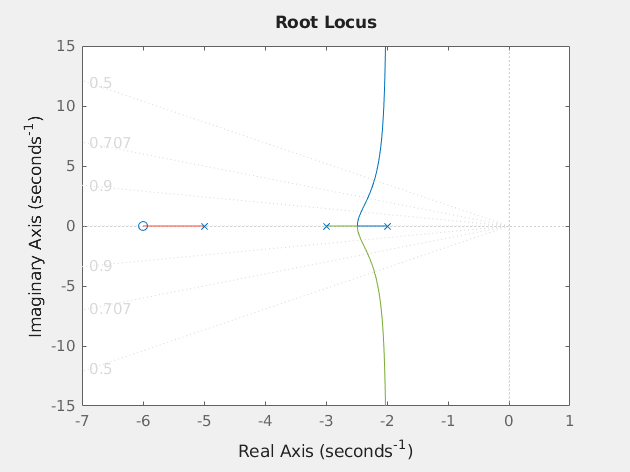

zeta = 0.707;
sgrid([0.5, zeta, 0.9],0);

*Find a value for the proportional gain, K, so that the the dominant closed-loop second order poles have a damping ratio of approximately ζ = 0.707. Report this value of gain, K.*

This next step is not necessary if using a regular script (.m file).   For a live script (.mlx file), this opens the figure in a separate figure window so that we can use the interactive UI to choose a gain point on the RL.

set(gcf,'Visible','on')

Graphically chosen point on the RL that puts the closed loop poles close to the zeta = 0.707 grid line.

K = 4.65;  % chosen gaphically

This next block is not explicilty part of the assigned problem, but is included to visualize the target closed-loop pole location.

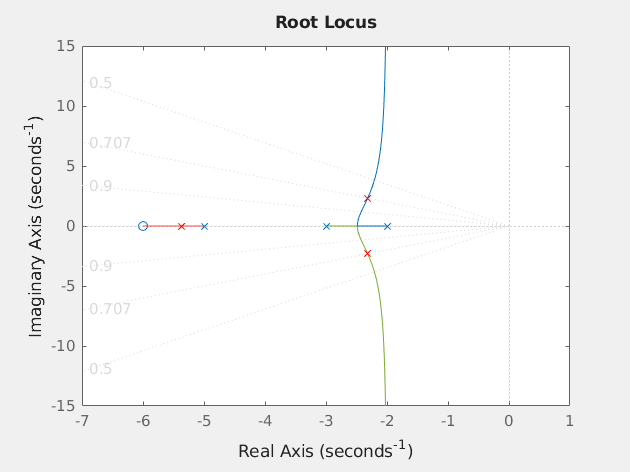

hold on;
r=rlocus(G,K);
plot(r,'rx')

% legend('RL',sprintf('Poles for K=%.2f',K))

#### Closed-loop response

*Using the proportional gain you found, create a closed-loop unit step response for the design and report the settling time and overshoot.*

Report settling time and overshoot.

T = feedback(K*G,1);
s =stepinfo(T);
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.32e+00 + 2.33e+00i     7.05e-01       3.28e+00         4.32e-01    
 -2.32e+00 - 2.33e+00i     7.05e-01       3.28e+00         4.32e-01    
 -5.37e+00                 1.00e+00       5.37e+00         1.86e-01    


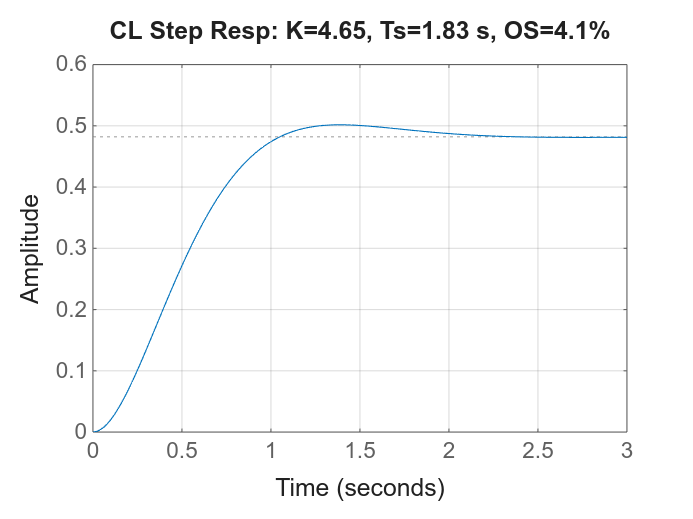

figure(2); clf();
step(T)
grid on
title(sprintf('CL Step Resp: K=%.2f, Ts=%.2f s, OS=%.1f%%', ...
    K,s.SettlingTime,s.Overshoot))

## Proportional-Derivative Compensator Design

Given design goal

Find target pole locations


$$T_s = \frac{4}{\zeta \omega_n} \:\:, \:  \text{so}  \:\:\zeta \omega_n = \frac{4}{T_s}$$


TsGoal = 0.92;
zetaomegan = 4/TsGoal

zetaomegan = 4.3478


$$s = -\zeta \omega_n \pm j \,\omega_d^2$$



$$\omega_d = \omega_n \sqrt{1-\zeta^2}$$


wn = zetaomegan/zeta;
wd = wn*sqrt(1-zeta^2);
poletgt = zetaomegan*[-1,-1]+wd*[i, -i]

poletgt =   -4.3478 + 4.3491i  -4.3478 - 4.3491i


#### Design the PD to cause RL to go through design goal

This section will be iterative.   You need to iterative try different locations of the zero location to find a value that causes the RL to pass near the target pole location.

pdzero = -7;   % chosen by trial-and-error

PD = zpk([pdzero],[],1);
L = PD * G;

figure(2); 
clf();
rlocusplot(L);
sgrid(0.707,0);
set(gcf,'Visible','on')

We can visualize the location of the poles by plotting them on the root locus graph.  This isn't necessary for your solution, but may help explain the process.

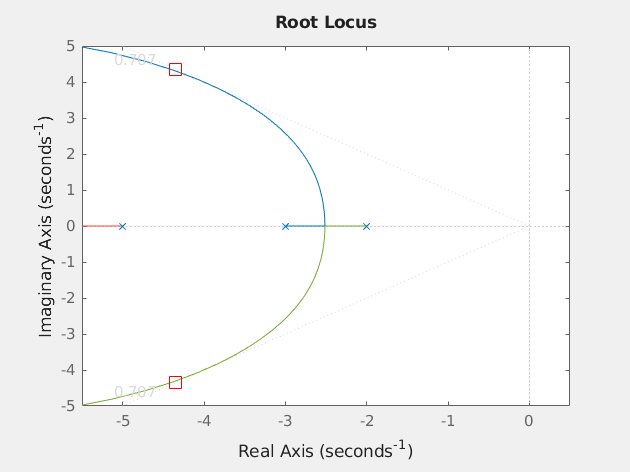

hold on
plot(real(poletgt),imag(poletgt),'rs','markersize',10)

xlim([-5.5,0.5])
ylim([-5 5])

## Find PD gain to put poles at the target

The `rlocus` plot has an interactive capability to display the gain value associated with a user selected point on the RL curve.  This is a little tempramental within the live script.  One of the following options should work for your setup

- Use the `set(gcf,'Visible','on')` command within the live script to display the standalone figure windown

- Within the live script, hover over the figure which should show a small icon,  , in the upper right corner.  Click on this to pop-out the figure window.

- Run the command rlocus command (e.g., `r=rlocus(PD*G,K2);`) directly in the Command Window.

You should be able to choose the gain value interactively like this...

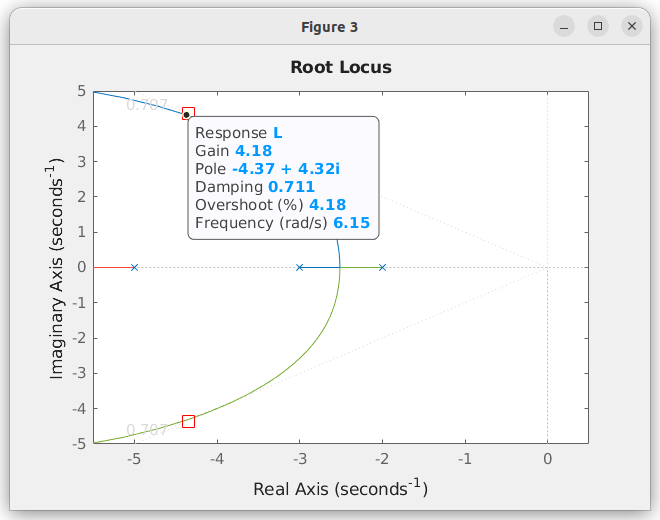

Include the gain value 

K2 = 4.18; % chosen graphically

Again, beyond what was asked for, but you can verify that this works by overlaying the root locus plot

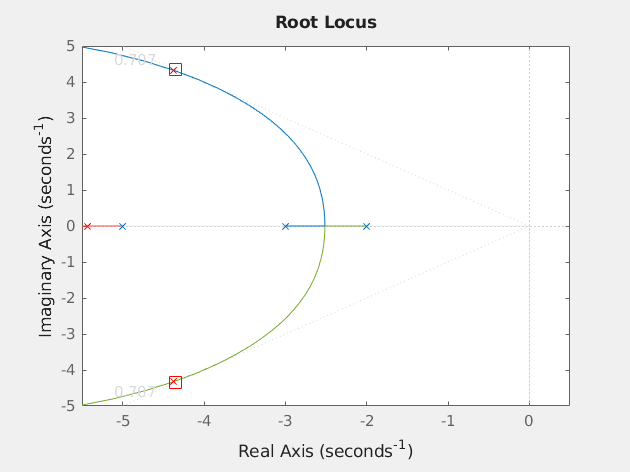

r=rlocus(PD*G,K2);
plot(r,'rx')

## Closed-Loop Step Response

Report the compensator design in the form: $D(s) = K_d (s + K_p/K_d)$


$$D(s) = 4.18 (s + 7)$$


Plot the P and PD step responses on the same graph.

figure(3); clf();
T = feedback(K*G,1);
step(T);  % Uncompensated (P control)
si = stepinfo(T);

hold on;
Tpd = feedback(K2*PD*G,1);
step(Tpd);  % Compensated (PD)
sipd = stepinfo(Tpd)

sipd = struct with fields:
         RiseTime: 0.2455
    TransientTime: 0.8387
     SettlingTime: 0.8387
      SettlingMin: 0.7796
      SettlingMax: 0.9126
        Overshoot: 6.8543
       Undershoot: 0
             Peak: 0.9126
         PeakTime: 0.5268


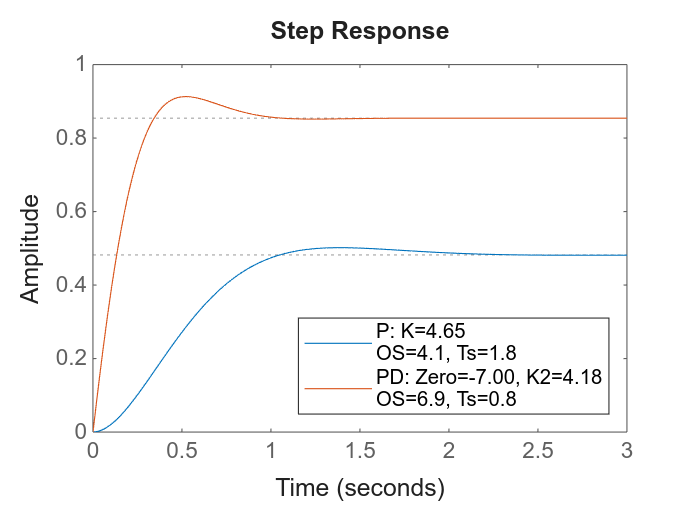

legend(sprintf('P: K=%.2f\nOS=%.1f, Ts=%.1f',K,si.Overshoot,si.SettlingTime),...
    sprintf('PD: Zero=%.2f, K2=%.2f\nOS=%.1f, Ts=%.1f',pdzero,K2,sipd.Overshoot,sipd.SettlingTime),...
    'location','southeast')